clc; clear; close all;

v = [14.2755 14.4695 13.6518 14.6806 14.5553];
f = 3000:500:5000;
k = 2*pi*f./v; 
h = 0.6002/2 * ones(size(v)) / 1000;

muestras = [3 4];
v = v(muestras);
f = f(muestras);
k = k(muestras);
h = h(muestras);

kh = k.*h;
% Valor inicial para fsolve
eta0 = 0.85;

% Opciones de fsolve
options = optimset('Display','off');

% Usamos arrayfun para aplicar fsolve a cada par (k(i), h(i))
eta_sol = arrayfun(@(khi) ...
    fsolve(@(eta) 4*eta.*tanh(eta*khi)./tanh(khi) - (1+eta.^2).^2, ...
           eta0, options), ...
    kh);

disp('Soluciones para eta:')

Soluciones para eta:


disp(eta_sol)

    0.8555    0.8458



rho = 1050;

x = eta_sol.^2

x =     0.7319    0.7154


y = rho*v.^2

y = 1.0e+05 *

    1.9569    2.2630


% Ajuste lineal (grado 1)
p = polyfit(x, y, 1);

% Pendiente y ordenada al origen
m = p(1);
b = p(2);

disp(['Recta ajustada: y = ' num2str(m) ' * x + ' num2str(b)])

Recta ajustada: y = -1850169.5615 * x + 1549852.2832


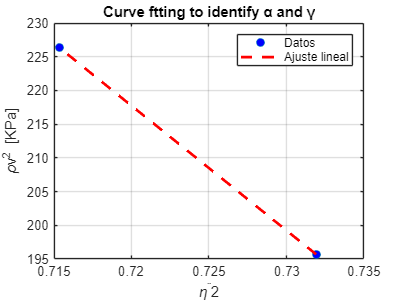


% Calcular valores ajustados
y_fit = polyval(p, x);

% Graficar
figure();
plot(x, y/1000, 'o', 'MarkerFaceColor', 'b'); hold on
plot(x, y_fit/1000, '--r', 'LineWidth', 2);
title('Curve ftting to identify α and γ')
legend('Datos', 'Ajuste lineal')
xlabel('\eta^¨2'); ylabel('\rhov^2 [KPa]');
grid on

% Resultados
alpha = b

alpha = 1.5499e+06

gamma = -m

gamma = 1.8502e+06


stress = alpha - gamma

stress = -3.0032e+05

strain = -1 + (alpha/gamma)^(1/3)

strain = -0.0573

young = stress/strain

young = 5.2384e+06